## Q1 - part c | RELS algorithm - Not Good at all

clear; clc;

%

load q1_402123100.mat

y_tilda = y-v;

u_val = u(length(u)/2+1:end);
v_val = v(length(u)/2+1:end);
z_val = z(length(u)/2+1:end);
y_val = y(length(u)/2+1:end);
y_tilda_val = y_tilda(length(u)/2+1:end);

u = u(1:length(u)/2);
v = v(1:length(v)/2);
z = z(1:length(z)/2);
y = y(1:length(y)/2);
y_tilda = y_tilda(1:length(y)/2);


Ts = 0.1; 
t = 0:Ts:length(u)*Ts-Ts;
N = length(y);
data = iddata(y,u,Ts);



fprintf("===============Degree Extraction | Best Fit Lowest Error Method====================\n")

===============Degree Extraction | Best Fit Lowest Error Method====================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 1;
iteration_number = 2000;
for degree=1:1:100
    na = degree;
    nb = degree;
    nc = degree;
    p = na+nb+nc+1;

%     UU = armax_error_U_builder(na,v);
%     dyn = inv(UU'*UU)*UU'*v;
%     vv = UU*dyn;
    
%     armax_U = armax_U_builder(na,nb,nc,u,y,z);
%     armax_theta_hat = inv(armax_U'*armax_U)*armax_U'*y;
    
    Theta0 = ones(p,1)*0.1;
    P0 = 100*eye(p);
    armax_theta_hat = run_iterative_armax(u, y, v, na, nb, nc, p, P0, Theta0, iteration_number);

    armax_y_hat = form_tf_lsim(armax_theta_hat, u, t, na, Ts);

%     armax_y_hat = armax_U*armax_theta_hat;

    [r2_armax, mse_armax] = rSQR(y, armax_y_hat);

    error = y - armax_y_hat;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end
    
    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);

%     covariance = variance*inv(armax_U'*armax_U);

    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f |\n", degree, r2_armax, mse_armax, variance)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    R2s = [R2s; r2_armax];
    MSEs = [MSEs; mse_armax];
%     dets = [dets; detUTU];
    vars = [vars; variance];

end

>>> Degree = 1 : R2=-0.024974 | MSE=4.307454 | var=4.342191 |


-------------------------------------------------------------


>>> Degree = 2 : R2=-0.020169 | MSE=4.287258 | var=4.348132 |


-------------------------------------------------------------


>>> Degree = 3 : R2=-0.020355 | MSE=4.288043 | var=4.375554 |


-------------------------------------------------------------


>>> Degree = 4 : R2=-0.017210 | MSE=4.274823 | var=4.388936 |


-------------------------------------------------------------


>>> Degree = 5 : R2=-0.009771 | MSE=4.243564 | var=4.383847 |


-------------------------------------------------------------


>>> Degree = 6 : R2=0.007881 | MSE=4.169381 | var=4.334076 |


-------------------------------------------------------------


>>> Degree = 7 : R2=0.007050 | MSE=4.172873 | var=4.364930 |


-------------------------------------------------------------


>>> Degree = 8 : R2=0.019927 | MSE=4.118758 | var=4.335535 |


-------------------------------------------------------------


>>> Degree = 9 : R2=0.039040 | MSE=4.038435 | var=4.278004 |


-------------------------------------------------------------


>>> Degree = 10 : R2=0.039905 | MSE=4.034801 | var=4.301494 |


-------------------------------------------------------------


>>> Degree = 11 : R2=0.067421 | MSE=3.919164 | var=4.205112 |


-------------------------------------------------------------


>>> Degree = 12 : R2=0.095761 | MSE=3.800063 | var=4.103740 |


-------------------------------------------------------------


>>> Degree = 13 : R2=0.124325 | MSE=3.680026 | var=4.000028 |


-------------------------------------------------------------


>>> Degree = 14 : R2=0.148848 | MSE=3.576964 | var=3.913528 |


-------------------------------------------------------------


>>> Degree = 15 : R2=0.164396 | MSE=3.511628 | var=3.867431 |


-------------------------------------------------------------


>>> Degree = 16 : R2=0.203824 | MSE=3.345931 | var=3.709458 |


-------------------------------------------------------------


>>> Degree = 17 : R2=0.237374 | MSE=3.204935 | var=3.576936 |


-------------------------------------------------------------


>>> Degree = 18 : R2=0.302701 | MSE=2.930401 | var=3.292585 |


-------------------------------------------------------------


>>> Degree = 19 : R2=0.307031 | MSE=2.912203 | var=3.294347 |


-------------------------------------------------------------


>>> Degree = 20 : R2=0.388797 | MSE=2.568582 | var=2.925491 |


-------------------------------------------------------------


>>> Degree = 21 : R2=0.431625 | MSE=2.388597 | var=2.739216 |


-------------------------------------------------------------


>>> Degree = 22 : R2=0.475789 | MSE=2.202998 | var=2.543877 |


-------------------------------------------------------------


>>> Degree = 23 : R2=0.511954 | MSE=2.051014 | var=2.384900 |


-------------------------------------------------------------


>>> Degree = 24 : R2=0.550548 | MSE=1.888822 | var=2.211735 |


-------------------------------------------------------------


>>> Degree = 25 : R2=0.578099 | MSE=1.773040 | var=2.090850 |


-------------------------------------------------------------


>>> Degree = 26 : R2=0.604034 | MSE=1.664049 | var=1.976305 |


-------------------------------------------------------------


>>> Degree = 27 : R2=0.629947 | MSE=1.555148 | var=1.860225 |


-------------------------------------------------------------


>>> Degree = 28 : R2=0.650407 | MSE=1.469165 | var=1.770079 |


-------------------------------------------------------------


>>> Degree = 29 : R2=0.665919 | MSE=1.403974 | var=1.703852 |


-------------------------------------------------------------


>>> Degree = 30 : R2=0.679151 | MSE=1.348366 | var=1.648370 |


-------------------------------------------------------------


>>> Degree = 31 : R2=0.688302 | MSE=1.309911 | var=1.613191 |


-------------------------------------------------------------


>>> Degree = 32 : R2=0.699446 | MSE=1.263080 | var=1.567097 |


-------------------------------------------------------------


>>> Degree = 33 : R2=0.706867 | MSE=1.231889 | var=1.539862 |


-------------------------------------------------------------


>>> Degree = 34 : R2=0.712695 | MSE=1.207401 | var=1.520656 |


-------------------------------------------------------------


>>> Degree = 35 : R2=0.718259 | MSE=1.184018 | var=1.502561 |


-------------------------------------------------------------


>>> Degree = 36 : R2=0.722864 | MSE=1.164666 | var=1.489342 |


-------------------------------------------------------------


>>> Degree = 37 : R2=0.726544 | MSE=1.149198 | var=1.480925 |


-------------------------------------------------------------


>>> Degree = 38 : R2=0.729811 | MSE=1.135471 | var=1.474637 |


-------------------------------------------------------------


>>> Degree = 39 : R2=0.730827 | MSE=1.131199 | var=1.480626 |


-------------------------------------------------------------


>>> Degree = 40 : R2=0.733868 | MSE=1.118418 | var=1.475486 |


-------------------------------------------------------------


>>> Degree = 41 : R2=0.735432 | MSE=1.111845 | var=1.478518 |


-------------------------------------------------------------


>>> Degree = 42 : R2=0.735613 | MSE=1.111087 | var=1.489392 |


-------------------------------------------------------------


>>> Degree = 43 : R2=0.736277 | MSE=1.108297 | var=1.497698 |


-------------------------------------------------------------


>>> Degree = 44 : R2=0.737704 | MSE=1.102298 | var=1.501768 |


-------------------------------------------------------------


>>> Degree = 45 : R2=-0.240020 | MSE=5.211183 | var=7.158219 |


-------------------------------------------------------------


>>> Degree = 46 : R2=0.735458 | MSE=1.111739 | var=1.539804 |


-------------------------------------------------------------


>>> Degree = 47 : R2=0.734340 | MSE=1.116438 | var=1.559270 |


-------------------------------------------------------------


>>> Degree = 48 : R2=0.734462 | MSE=1.115924 | var=1.571724 |


-------------------------------------------------------------


>>> Degree = 49 : R2=0.731269 | MSE=1.129343 | var=1.604181 |


-------------------------------------------------------------


>>> Degree = 50 : R2=0.729904 | MSE=1.135079 | var=1.626188 |


-------------------------------------------------------------


>>> Degree = 51 : R2=0.727835 | MSE=1.143774 | var=1.652853 |


-------------------------------------------------------------


>>> Degree = 52 : R2=0.725493 | MSE=1.153617 | var=1.681657 |


-------------------------------------------------------------


>>> Degree = 53 : R2=0.722953 | MSE=1.164289 | var=1.712189 |


-------------------------------------------------------------


>>> Degree = 54 : R2=0.720380 | MSE=1.175103 | var=1.743477 |


-------------------------------------------------------------


>>> Degree = 55 : R2=0.719372 | MSE=1.179338 | var=1.765477 |


-------------------------------------------------------------


>>> Degree = 56 : R2=0.718886 | MSE=1.181382 | var=1.784565 |


-------------------------------------------------------------


>>> Degree = 57 : R2=0.711049 | MSE=1.214316 | var=1.851092 |


-------------------------------------------------------------


>>> Degree = 58 : R2=0.706706 | MSE=1.232567 | var=1.896257 |


-------------------------------------------------------------


>>> Degree = 59 : R2=0.706793 | MSE=1.232201 | var=1.913355 |


-------------------------------------------------------------


>>> Degree = 60 : R2=0.694830 | MSE=1.282477 | var=2.010151 |


-------------------------------------------------------------


>>> Degree = 61 : R2=0.686849 | MSE=1.316015 | var=2.082303 |


-------------------------------------------------------------


>>> Degree = 62 : R2=0.676536 | MSE=1.359356 | var=2.171495 |


-------------------------------------------------------------


>>> Degree = 63 : R2=0.665380 | MSE=1.406242 | var=2.268133 |


-------------------------------------------------------------


>>> Degree = 64 : R2=0.650179 | MSE=1.470121 | var=2.394334 |


-------------------------------------------------------------


>>> Degree = 65 : R2=0.626037 | MSE=1.571578 | var=2.584832 |


-------------------------------------------------------------


>>> Degree = 66 : R2=0.608942 | MSE=1.643419 | var=2.729932 |


-------------------------------------------------------------


>>> Degree = 67 : R2=0.586715 | MSE=1.736831 | var=2.914146 |


-------------------------------------------------------------


>>> Degree = 68 : R2=0.536445 | MSE=1.948089 | var=3.301846 |


-------------------------------------------------------------


>>> Degree = 69 : R2=0.523120 | MSE=2.004089 | var=3.431659 |


-------------------------------------------------------------


>>> Degree = 70 : R2=0.494285 | MSE=2.125268 | var=3.676934 |


-------------------------------------------------------------


>>> Degree = 71 : R2=0.471396 | MSE=2.221459 | var=3.883669 |


-------------------------------------------------------------


>>> Degree = 72 : R2=0.450377 | MSE=2.309793 | var=4.080906 |


-------------------------------------------------------------


>>> Degree = 73 : R2=0.435760 | MSE=2.371220 | var=4.234321 |


-------------------------------------------------------------


>>> Degree = 74 : R2=0.429728 | MSE=2.396569 | var=4.325937 |


-------------------------------------------------------------


>>> Degree = 75 : R2=0.468459 | MSE=2.233799 | var=4.076276 |


-------------------------------------------------------------


>>> Degree = 76 : R2=0.440194 | MSE=2.352585 | var=4.340562 |


-------------------------------------------------------------


>>> Degree = 77 : R2=0.444595 | MSE=2.334088 | var=4.354641 |


-------------------------------------------------------------


>>> Degree = 78 : R2=0.440247 | MSE=2.352362 | var=4.438419 |


-------------------------------------------------------------


>>> Degree = 79 : R2=0.442903 | MSE=2.341198 | var=4.467935 |


-------------------------------------------------------------


>>> Degree = 80 : R2=0.413644 | MSE=2.464160 | var=4.757065 |


-------------------------------------------------------------


>>> Degree = 81 : R2=0.371898 | MSE=2.639598 | var=5.155465 |


-------------------------------------------------------------


>>> Degree = 82 : R2=0.340333 | MSE=2.772252 | var=5.478759 |


-------------------------------------------------------------


>>> Degree = 83 : R2=0.259104 | MSE=3.113615 | var=6.227230 |


-------------------------------------------------------------


>>> Degree = 84 : R2=0.209909 | MSE=3.320359 | var=6.721374 |


-------------------------------------------------------------


>>> Degree = 85 : R2=0.197033 | MSE=3.374469 | var=6.914895 |


-------------------------------------------------------------


>>> Degree = 86 : R2=0.150346 | MSE=3.570673 | var=7.408035 |


-------------------------------------------------------------


>>> Degree = 87 : R2=0.107942 | MSE=3.748875 | var=7.875788 |


-------------------------------------------------------------


>>> Degree = 88 : R2=-1133300.321004 | MSE=4762698.945151 | var=10133402.010959 |


-------------------------------------------------------------


>>> Degree = 89 : R2=0.079125 | MSE=3.869979 | var=8.340471 |


-------------------------------------------------------------


>>> Degree = 90 : R2=0.097412 | MSE=3.793125 | var=8.281931 |


-------------------------------------------------------------


>>> Degree = 91 : R2=0.107967 | MSE=3.748768 | var=8.293733 |


-------------------------------------------------------------


>>> Degree = 92 : R2=0.097382 | MSE=3.793251 | var=8.505046 |


-------------------------------------------------------------


>>> Degree = 93 : R2=0.199196 | MSE=3.365381 | var=7.648593 |


-------------------------------------------------------------


>>> Degree = 94 : R2=-7.828108 | MSE=37.100127 | var=85.484163 |


-------------------------------------------------------------


>>> Degree = 95 : R2=0.241451 | MSE=3.187800 | var=7.448132 |


-------------------------------------------------------------


>>> Degree = 96 : R2=0.298598 | MSE=2.947641 | var=6.984931 |


-------------------------------------------------------------


>>> Degree = 97 : R2=0.483635 | MSE=2.170024 | var=5.216404 |


-------------------------------------------------------------


>>> Degree = 98 : R2=0.538744 | MSE=1.938427 | var=4.727871 |


-------------------------------------------------------------


>>> Degree = 99 : R2=0.559782 | MSE=1.850018 | var=4.579253 |


-------------------------------------------------------------


>>> Degree = 100 : R2=0.540271 | MSE=1.932013 | var=4.854304 |


-------------------------------------------------------------


fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 44 


na = bestFitDegree;
nb = bestFitDegree;
nc = bestFitDegree;
p = na+nb+nc+1;

% UU = armax_error_U_builder(na,v);
% dyn = inv(UU'*UU)*UU'*v;
% v = UU*dyn;
%     
% armax_U = armax_U_builder(na,nb,nc,u,y,v);
% BestFitModel = inv(armax_U'*armax_U)*armax_U'*y;

Theta0 = zeros(p,1);
P0 = 100*eye(p);
BestFitModel = run_iterative_armax(u, y, v, na, nb, nc, p, P0, Theta0, iteration_number);

BestFit_y_hat = form_tf_lsim(BestFitModel, u_val, t, na, Ts);

G =
 
                                                                                                          
  -0.003182 z^44 - 0.0002734 z^43 + 0.00382 z^42 + 0.009519 z^41 + 0.01703 z^40 + 0.0249 z^39             
                                                                                                          
          + 0.03109 z^38 + 0.03747 z^37 + 0.04268 z^36 + 0.04622 z^35 + 0.04887 z^34 + 0.05066 z^33       
                                                                                                          
          + 0.05009 z^32 + 0.04907 z^31 + 0.04604 z^30 + 0.0421 z^29 + 0.03908 z^28 + 0.03478 z^27        
                                                                                                          
          + 0.02943 z^26 + 0.02434 z^25 + 0.02006 z^24 + 0.01522 z^23 + 0.01183 z^22 + 0.00807 z^21       
                                                                                                          
          + 0.004754 z^20 + 0.0

%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars),1);
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 38 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 38 


na = minVarIndex;
nb = minVarIndex;
nc = minVarIndex;
p = na+nb+nc+1;

% UU = armax_error_U_builder(na,v);
% dyn = inv(UU'*UU)*UU'*v;
% v = UU*dyn;
% 
% armax_VarU = armax_U_builder(na,nb,nc,u,y,v);
% armax_VarModel = inv(armax_VarU'*armax_VarU)*armax_VarU'*y;

Theta0 = zeros(p,1);
P0 = 100*eye(p);
armax_VarModel = run_iterative_armax(u, y, v, na, nb, nc, p, P0, Theta0, iteration_number);

Var_y_hat = form_tf_lsim(armax_VarModel, u_val, t, na, Ts);

G =
 
                                                                                                      
  -0.002032 z^38 + 0.0004285 z^37 + 0.004222 z^36 + 0.009968 z^35 + 0.01699 z^34 + 0.02466 z^33       
                                                                                                      
          + 0.03123 z^32 + 0.03788 z^31 + 0.04301 z^30 + 0.04646 z^29 + 0.04878 z^28 + 0.0502 z^27    
                                                                                                      
          + 0.04936 z^26 + 0.04812 z^25 + 0.0453 z^24 + 0.04177 z^23 + 0.03843 z^22 + 0.03433 z^21    
                                                                                                      
          + 0.02929 z^20 + 0.02467 z^19 + 0.02077 z^18 + 0.01658 z^17 + 0.01324 z^16 + 0.009954 z^15  
                                                                                                      
          + 0.007259 z^14 + 0.004336 z^13 + 0.003096 z^12 + 0.00076


fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=1.00) occurs in iteration 36 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 36 



na = minAICIndex;
nb = minAICIndex;
nc = minAICIndex;
p = na+nb+nc+1;

% UU = armax_error_U_builder(na,v);
% dyn = inv(UU'*UU)*UU'*v;
% v = UU*dyn;
% 
% armax_AICU = armax_U_builder(na,nb,nc,u,y,v);
% armax_AICModel = inv(armax_AICU'*armax_AICU)*armax_AICU'*y;

Theta0 = zeros(p,1);
P0 = 100*eye(p);
armax_AICModel = run_iterative_armax(u, y, v, na, nb, nc, p, P0, Theta0, iteration_number);


AIC_y_hat = form_tf_lsim(armax_AICModel, u_val, t, na, Ts);

G =
 
                                                                                                        
   -0.005213 z^36 - 0.002721 z^35 + 0.000617 z^34 + 0.00662 z^33 + 0.01279 z^32 + 0.02082 z^31          
                                                                                                        
           + 0.02729 z^30 + 0.0347 z^29 + 0.04007 z^28 + 0.04194 z^27 + 0.04415 z^26 + 0.04482 z^25     
                                                                                                        
           + 0.04385 z^24 + 0.044 z^23 + 0.04347 z^22 + 0.03963 z^21 + 0.03666 z^20 + 0.03249 z^19      
                                                                                                        
           + 0.02664 z^18 + 0.02458 z^17 + 0.0199 z^16 + 0.0153 z^15 + 0.01361 z^14 + 0.01053 z^13      
                                                                                                        
           + 0.009671 z^12 + 0.008087 z^11 + 0.00


fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.22 as


fprintf("    Degree = %d \n", winner)

    Degree = 36 



na = winner;
nb = winner;
nc = winner;
p = na+nb+nc+1;

% UU = armax_error_U_builder(na,v);
% dyn = inv(UU'*UU)*UU'*v;
% v = UU*dyn;
% 
% armax_FTestU = armax_U_builder(na,nb,nc,u,y,v);
% armax_FTestModel = inv(armax_FTestU'*armax_FTestU)*armax_FTestU'*y;

Theta0 = zeros(p,1);
P0 = 100*eye(p);
armax_FTestModel = run_iterative_armax(u, y, v, na, nb, nc, p, P0, Theta0, iteration_number);

FTest_y_hat = form_tf_lsim(armax_FTestModel, u_val, t, na, Ts);

G =
 
                                                                                                        
   -0.005213 z^36 - 0.002721 z^35 + 0.000617 z^34 + 0.00662 z^33 + 0.01279 z^32 + 0.02082 z^31          
                                                                                                        
           + 0.02729 z^30 + 0.0347 z^29 + 0.04007 z^28 + 0.04194 z^27 + 0.04415 z^26 + 0.04482 z^25     
                                                                                                        
           + 0.04385 z^24 + 0.044 z^23 + 0.04347 z^22 + 0.03963 z^21 + 0.03666 z^20 + 0.03249 z^19      
                                                                                                        
           + 0.02664 z^18 + 0.02458 z^17 + 0.0199 z^16 + 0.0153 z^15 + 0.01361 z^14 + 0.01053 z^13      
                                                                                                        
           + 0.009671 z^12 + 0.008087 z^11 + 0.00


fprintf("=================================================================\n")

%%

[BestFit_r2, BestFit_mse] = rSQR(y_val, BestFit_y_hat);
[Var_r2, Var_mse] = rSQR(y_val, Var_y_hat);
[AIC_r2, AIC_mse] = rSQR(y_val, AIC_y_hat);
[FTest_r2, FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", BestFit_r2, BestFit_mse)

    R2 value : 0.5670   | MSE : 2.3981 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", Var_r2, Var_mse)

    R2 value : 0.5517   | MSE : 2.4824 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", AIC_r2, AIC_mse)

    R2 value : 0.4711   | MSE : 2.9288 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", FTest_r2, FTest_mse)

    R2 value : 0.4711   | MSE : 2.9288 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Winner:\n")

>>> Winner:


fprintf("    The best R2 value is \n")

    The best R2 value is 


fprintf("===============================================================\n")

%%

armax_BestFitError = y_val - BestFit_y_hat;
armax_VarError = y_val - Var_y_hat;
armax_AICError = y_val - AIC_y_hat;
armax_FTestError = y_val - FTest_y_hat;

for k=0:N-1
    armax_BestFit_Ree(k+1,1) = AutoCorrelate(armax_BestFitError, k);
    armax_Var_Ree(k+1,1) = AutoCorrelate(armax_VarError, k);
    armax_AIC_Ree(k+1,1) = AutoCorrelate(armax_AICError, k);
    armax_FTest_Ree(k+1,1) = AutoCorrelate(armax_FTestError, k);
end

for k=0:N-1
    armax_BestFit_Rue(k+1,1) = CrossCorrelate(u_val, armax_BestFitError, k);
    armax_Var_Rue(k+1,1) = CrossCorrelate(u_val, armax_VarError, k);
    armax_AIC_Rue(k+1,1) = CrossCorrelate(u_val, armax_AICError, k);
    armax_FTest_Rue(k+1,1) = CrossCorrelate(u_val, armax_FTestError, k);
end


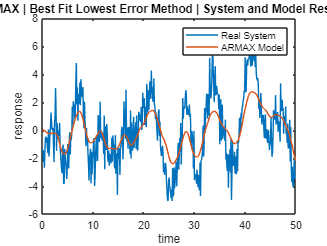

%%
figure(1)
plot(t,y_val,t,BestFit_y_hat)
legend('Real System','ARMAX Model')
title(" ARMAX | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

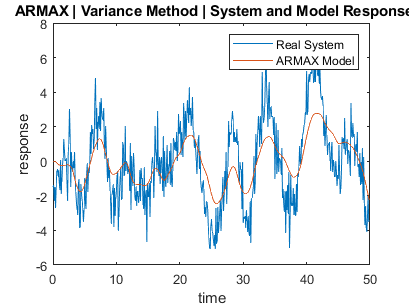


figure(2)
plot(t,y_val,t,Var_y_hat)
legend('Real System','ARMAX Model')
title(" ARMAX | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

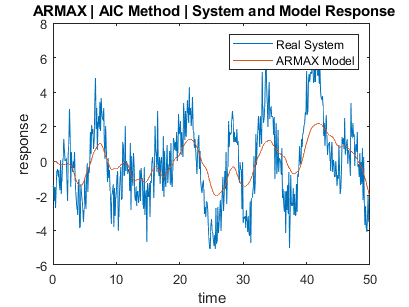


figure(3)
plot(t,y_val,t,AIC_y_hat)
legend('Real System','ARMAX Model')
title(" ARMAX | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

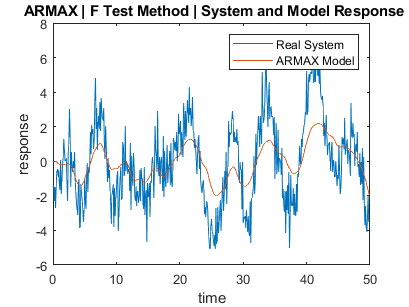


figure(4)
plot(t,y_val,t,FTest_y_hat)
legend('Real System','ARMAX Model')
title(" ARMAX | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

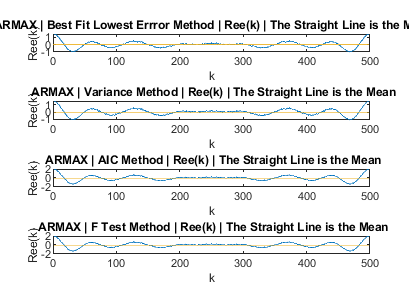

%%

figure(5)
subplot(4,1,1)
plot(1:N-1,armax_BestFit_Ree(2:end), 1:N-1, mean(armax_BestFit_Ree(2:end))*ones(length(1:N-1)))
title(" ARMAX | Best Fit Lowest Errror Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(4,1,2)
plot(1:N-1,armax_Var_Ree(2:end), 1:N-1, mean(armax_Var_Ree(2:end))*ones(length(1:N-1)))
title(" ARMAX | Variance Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(4,1,3)
plot(1:N-1,armax_AIC_Ree(2:end), 1:N-1, mean(armax_AIC_Ree(2:end))*ones(length(1:N-1)))
title(" ARMAX | AIC Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(4,1,4)
plot(1:N-1,armax_FTest_Ree(2:end), 1:N-1, mean(armax_FTest_Ree(2:end))*ones(length(1:N-1)))
title(" ARMAX | F Test Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

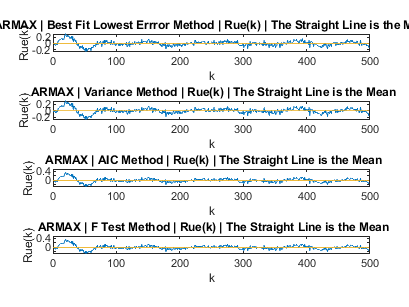

%%

figure(6)
subplot(4,1,1)
plot(1:N-1,armax_BestFit_Rue(2:end), 1:N-1, mean(armax_BestFit_Rue(2:end))*ones(length(1:N-1)))
title(" ARMAX | Best Fit Lowest Errror Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(4,1,2)
plot(1:N-1,armax_Var_Rue(2:end), 1:N-1, mean(armax_Var_Rue(2:end))*ones(length(1:N-1)))
title(" ARMAX | Variance Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(4,1,3)
plot(1:N-1,armax_AIC_Rue(2:end), 1:N-1, mean(armax_AIC_Rue(2:end))*ones(length(1:N-1)))
title(" ARMAX | AIC Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(4,1,4)
plot(1:N-1,armax_FTest_Rue(2:end), 1:N-1, mean(armax_FTest_Rue(2:end))*ones(length(1:N-1)))
title(" ARMAX | F Test Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

%% 

figure(7)

denom = armax_AICModel(1:minAICIndex);
num = armax_AICModel(minAICIndex+1:minAICIndex*2);
G = tf(num', [1 denom'], 'Ts', Ts);
G_AIC_poles = pole(G);

fprintf(">>> We have used  u, y and v for model estimation under ARMAX structure. \n")

>>> We have used  u, y and v for model estimation under ARMAX structure. 


fprintf("    Accordingly, the transfer function of the proper system degree is as follows:\n")

    Accordingly, the transfer function of the proper system degree is as follows:


fprintf(" G(z) = \n")

 G(z) = 


disp(G)

  tf with properties:

       Numerator: {[0 -0.0052 -0.0027 6.1696e-04 0.0066 0.0128 0.0208 0.0273 0.0347 0.0401 0.0419 0.0441 … ]}
     Denominator: {[1 -0.5884 -0.0780 -0.0686 -0.0587 -0.0501 -0.0418 -0.0331 -0.0261 -0.0191 -0.0139 … ]}
        Variable: 'z'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
              Ts: 0.1000
        TimeUnit: 'seconds'
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
    SamplingGrid: [1×1 struct]



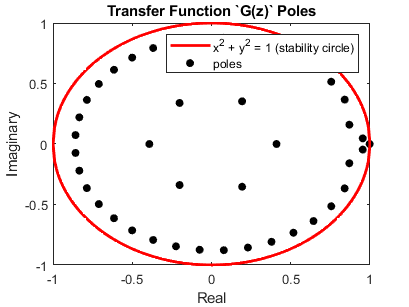


xx = -1:0.01:+1;
yy = [sqrt(1-xx.^2), flip(-sqrt(1-xx.^2))];
xx = [xx flip(xx)];


plot(xx, yy, LineWidth=2, Color="red")
hold on
scatter(real(G_AIC_poles), imag(G_AIC_poles), 'fill', 'black')
legend("x^2 + y^2 = 1 (stability circle)", "poles")
title("Transfer Function `G(z)` Poles")
xlabel("Real")
ylabel("Imaginary")



fprintf(">>> It is shown in the figure that all the poles are in the stability circle area and \n")

>>> It is shown in the figure that all the poles are in the stability circle area and 


fprintf("    hence, they are all stable. Therefre the estimated model in stable. \n")

    hence, they are all stable. Therefre the estimated model in stable. 
